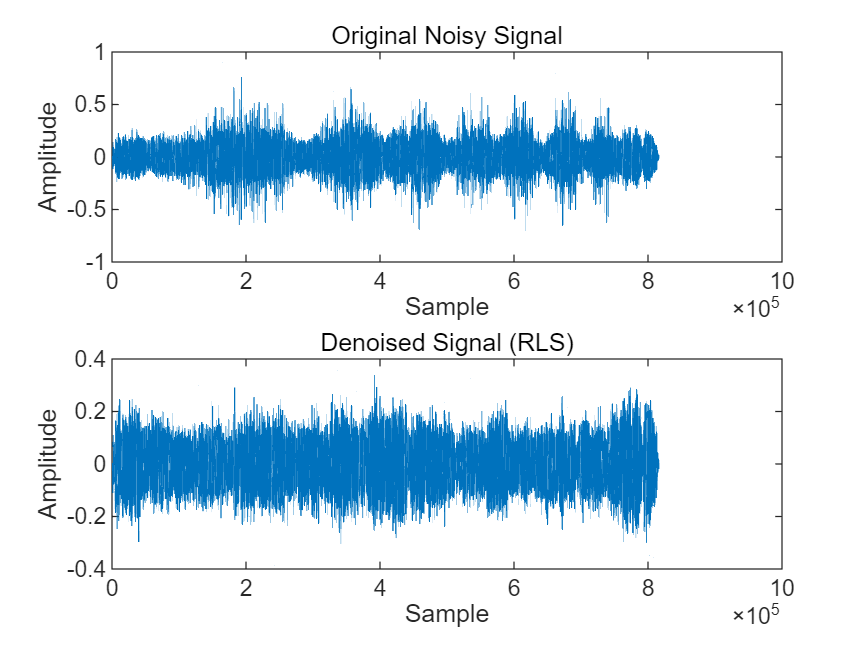

clear; clc; close all;

%% Load Data
load('Hw2c.mat');  % Variables: Sin_c, Sn_ref_c, fs

noisy_signal = Sin_c(:,1);  % Use left channel
ref_signal = [Sn_ref_c(:,2); Sn_ref_c(:,1)];  % Concatenate right then left reference channels

%% RLS Parameters
M = 32;             % Filter order
lambda = 0.99;      % Forgetting factor
delta = 1;          % Initial scale for P matrix
N = length(noisy_signal);

% Initialize
W = zeros(M,1);            % Filter weights
P = eye(M) / delta;        % Initial inverse correlation matrix
clean_signal = zeros(N,1); % Output signal

%% RLS Filtering (backward)
for k = N-M+1:-1:1
    x = ref_signal(k:k+M-1);     % Reference input vector
    d = noisy_signal(k);         % Desired signal
    K = P * x / (lambda + x' * P * x);  % Gain vector
    e = d - W' * x;              % Error between desired and estimated
    W = W + K * e;               % Update weights
    P = (P - K * x' * P) / lambda;  % Update inverse correlation matrix
    clean_signal(k) = e;         % Store output
end

% Normalize signals for playback and visualization
clean_signal = clean_signal / (max(abs(clean_signal)) + max(abs(noisy_signal)));
noisy_signal = noisy_signal / (max(abs(clean_signal)) + max(abs(noisy_signal)));

%% Playback
sound(clean_signal, fs);

%% Plot: Full waveform
figure;
subplot(2,1,1); plot(noisy_signal); title('Original Noisy Signal');
xlabel('Sample'); ylabel('Amplitude');

subplot(2,1,2); plot(clean_signal); title('Denoised Signal (RLS)');
xlabel('Sample'); ylabel('Amplitude');

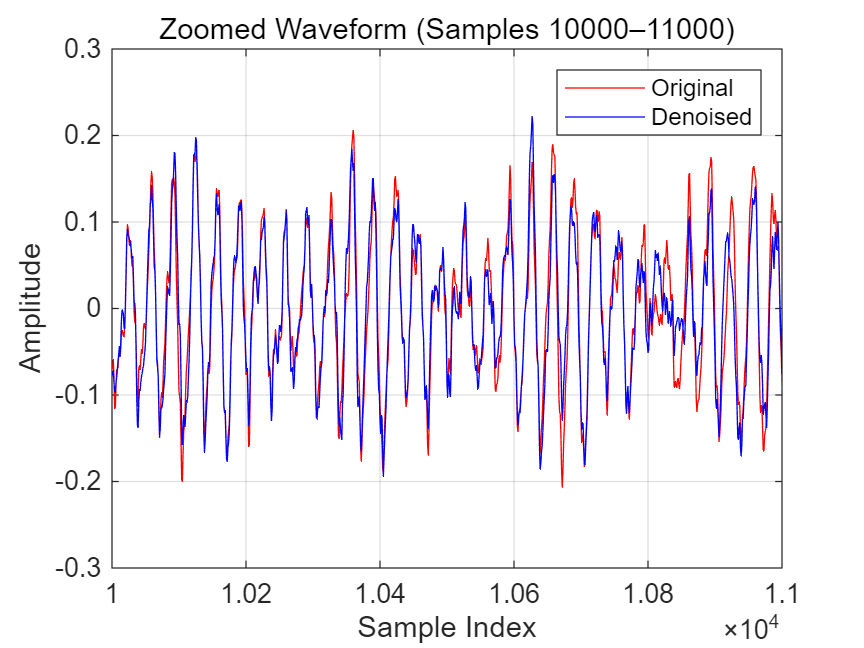


%% Plot: Zoomed comparison (samples 10000–11000)
figure;
plot(10000:11000, noisy_signal(10000:11000), 'r'); hold on;
plot(10000:11000, clean_signal(10000:11000), 'b');
legend('Original','Denoised');
title('Zoomed Waveform (Samples 10000–11000)');
xlabel('Sample Index'); ylabel('Amplitude'); grid on;

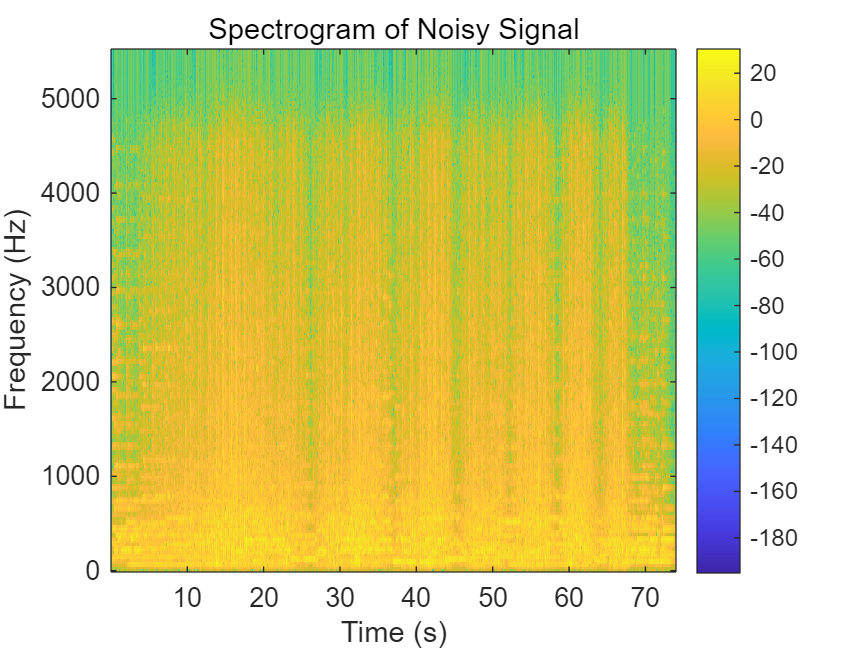


%% Plot: Spectrograms
N_win = 400;
overlap = N_win / 2;
window = hamming(N_win);

figure;
[S1, F1, T1] = spectrogram(noisy_signal, window, overlap, N_win, fs);
imagesc(T1, F1, 20*log10(abs(S1))); axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Spectrogram of Noisy Signal');
colorbar;

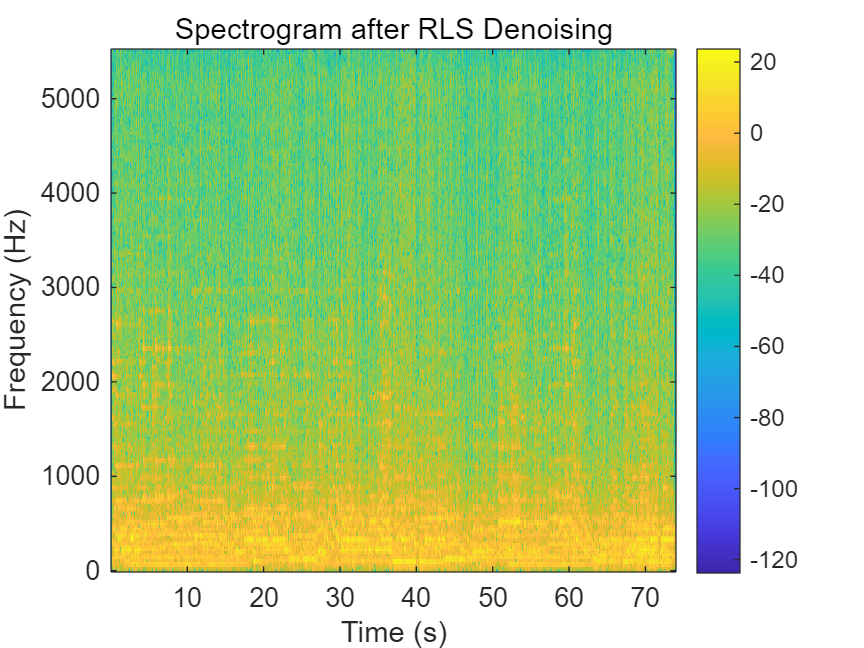


figure;
[S2, F2, T2] = spectrogram(clean_signal, window, overlap, N_win, fs);
imagesc(T2, F2, 20*log10(abs(S2))); axis xy;
xlabel('Time (s)'); ylabel('Frequency (Hz)');
title('Spectrogram after RLS Denoising');
colorbar;

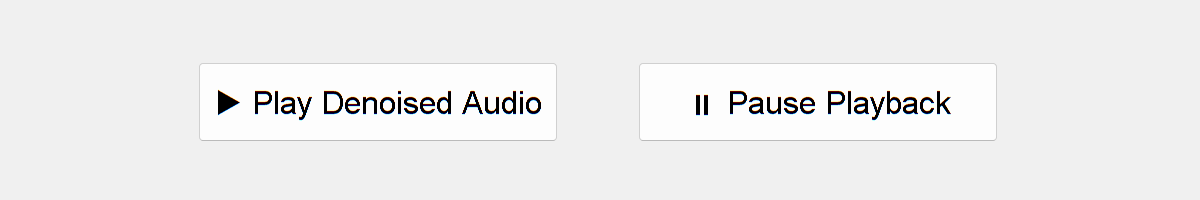


%% UI Playback Controls

% Add simple playback control buttons
f_ui = figure('Name','Playback Controls','Position',[300 300 600 100]);

uicontrol('Style','pushbutton','String','▶ Play Denoised Audio', ...
          'Position',[100 30 180 40],'FontSize',12, ...
          'Callback','sound(clean_signal, fs)');

uicontrol('Style','pushbutton','String','⏸ Pause Playback', ...
          'Position',[320 30 180 40],'FontSize',12, ...
          'Callback','clear sound');